# Chapter 5 #: 1, 2, 3, 4, 6, 7, 10, 15

## Problem 1


fprintf('Problem 1\n')

Problem 1


clear all
A=[3, 0, -2; 0, 1, 2; 0, -2, 1]

A =      3     0    -2
     0     1     2
     0    -2     1


lambda=eig(A) %calculates eigenvalues of A

lambda =    3.0000 + 0.0000i
   1.0000 + 2.0000i
   1.0000 - 2.0000i


[v,d]=eig(A) %calculates eigenvalues AND eigenvectors of A

v =    1.0000 + 0.0000i   0.3162 + 0.3162i   0.3162 - 0.3162i
   0.0000 + 0.0000i   0.0000 - 0.6325i   0.0000 + 0.6325i
   0.0000 + 0.0000i   0.6325 + 0.0000i   0.6325 + 0.0000i


d =    3.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.0000 + 2.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 - 2.0000i


%eigenvectors given as columns of v
%corresponding eigenvalues are on diagonal of d
lambda=eig(sym(A)) %uses sym to find and display eigenvalues

$$lambda = \left(\begin{array}{c} 3\\ 1-2\,\mathrm{i}\\ 1+2\,\mathrm{i} \end{array}\right)$$

[v,d]=eig(sym(A))

$$v = \left(\begin{array}{ccc} 1 & \frac{1}{2}-\frac{1}{2}\,\mathrm{i} & \frac{1}{2}+\frac{1}{2}\,\mathrm{i}\\ 0 & \mathrm{i} & -\mathrm{i}\\ 0 & 1 & 1 \end{array}\right)$$

$$d = \left(\begin{array}{ccc} 3 & 0 & 0\\ 0 & 1-2\,\mathrm{i} & 0\\ 0 & 0 & 1+2\,\mathrm{i} \end{array}\right)$$

d(1,1) %first eigenvalue of A

$$ans = 3$$

v(:,1) %corresponding first eigenvector of A

$$ans = \left(\begin{array}{c} 1\\ 0\\ 0 \end{array}\right)$$

A*v(:,1)

$$ans = \left(\begin{array}{c} 3\\ 0\\ 0 \end{array}\right)$$

d(1,1)*v(:,1) %verifies that A*v=lambda*v for first

$$ans = \left(\begin{array}{c} 3\\ 0\\ 0 \end{array}\right)$$

% eigenvalue-eigenvector pair; the last two
%answers should be identical
A*v(:,3)

$$ans = \left(\begin{array}{c} -\frac{1}{2}+\frac{3}{2}\,\mathrm{i}\\ 2-\mathrm{i}\\ 1+2\,\mathrm{i} \end{array}\right)$$

d(3,3)*v(:,3) %verifies that A*v=lambda*v for third

$$ans = \left(\begin{array}{c} -\frac{1}{2}+\frac{3}{2}\,\mathrm{i}\\ 2-\mathrm{i}\\ 1+2\,\mathrm{i} \end{array}\right)$$

## Problem 2


fprintf('Problem 2\n')

Problem 2


clear all
A=[-2,-1,-2; -4,-5,2; -5,-1,1]

A =     -2    -1    -2
    -4    -5     2
    -5    -1     1


[v,d]=eig(sym(A))

$$v = \left(\begin{array}{ccc} 1 & -\frac{1}{2} & 1\\ -1 & \frac{1}{2} & 2\\ 1 & 1 & 1 \end{array}\right)$$

$$d = \left(\begin{array}{ccc} -3 & 0 & 0\\ 0 & 3 & 0\\ 0 & 0 & -6 \end{array}\right)$$

syms t c1 c2 c3
%Type the line below on a single line, not with a <return>.
soln=[exp(d(1,1)*t)*v(:,1),exp(d(2,2)*t)*v(:,2),exp(d(3,3)*t)*v(:,3)]

$$soln = \left(\begin{array}{ccc} {\mathrm{e}}^{-3\,t} & -\frac{{\mathrm{e}}^{3\,t}}{2} & {\mathrm{e}}^{-6\,t}\\ -{\mathrm{e}}^{-3\,t} & \frac{{\mathrm{e}}^{3\,t}}{2} & 2\,{\mathrm{e}}^{-6\,t}\\ {\mathrm{e}}^{-3\,t} & {\mathrm{e}}^{3\,t} & {\mathrm{e}}^{-6\,t} \end{array}\right)$$

%general soln is soln*[c1; c2; c3]
soln0=subs(soln,t,0)

$$soln0 = \left(\begin{array}{ccc} 1 & -\frac{1}{2} & 1\\ -1 & \frac{1}{2} & 2\\ 1 & 1 & 1 \end{array}\right)$$

x0=[2; -1; -3]

x0 =      2
    -1
    -3


cvals=soln0\x0

$$cvals = \left(\begin{array}{c} 0\\ -\frac{10}{3}\\ \frac{1}{3} \end{array}\right)$$

v1n=v(:,1)*cvals(1)

$$v1n = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

v2n=v(:,2)*cvals(2)

$$v2n = \left(\begin{array}{c} \frac{5}{3}\\ -\frac{5}{3}\\ -\frac{10}{3} \end{array}\right)$$

v3n=v(:,3)*cvals(3)

$$v3n = \left(\begin{array}{c} \frac{1}{3}\\ \frac{2}{3}\\ \frac{1}{3} \end{array}\right)$$

Vmat=[v1n,v2n,v3n]

$$Vmat = \left(\begin{array}{ccc} 0 & \frac{5}{3} & \frac{1}{3}\\ 0 & -\frac{5}{3} & \frac{2}{3}\\ 0 & -\frac{10}{3} & \frac{1}{3} \end{array}\right)$$

xvec=[exp(d(1,1)*t); exp(d(2,2)*t); exp(d(3,3)*t)]

$$xvec = \left(\begin{array}{c} {\mathrm{e}}^{-3\,t}\\ {\mathrm{e}}^{3\,t}\\ {\mathrm{e}}^{-6\,t} \end{array}\right)$$

soln=Vmat*xvec %the solution to the IVP

$$soln = \left(\begin{array}{c} \frac{5\,{\mathrm{e}}^{3\,t}}{3}+\frac{{\mathrm{e}}^{-6\,t}}{3}\\ \frac{2\,{\mathrm{e}}^{-6\,t}}{3}-\frac{5\,{\mathrm{e}}^{3\,t}}{3}\\ \frac{{\mathrm{e}}^{-6\,t}}{3}-\frac{10\,{\mathrm{e}}^{3\,t}}{3} \end{array}\right)$$

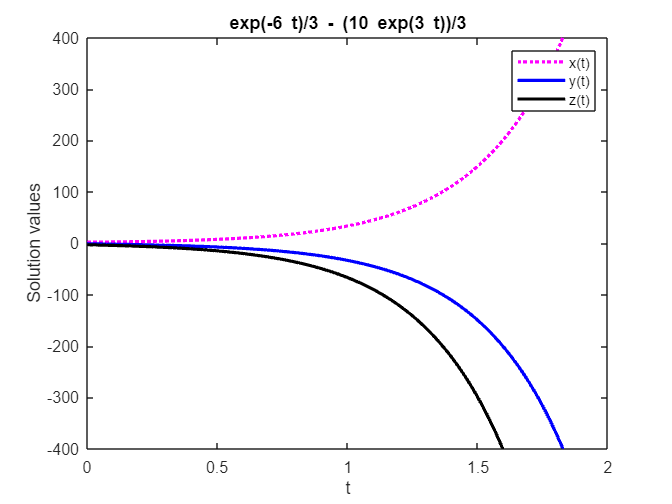

h1=ezplot(soln(1),[0,2]);
set(h1,'Color','m','LineStyle',':','LineWidth',2)
hold on
h2=ezplot(soln(2),[0,2]);
set(h2,'Color','b','LineStyle','-','LineWidth',2)
h3=ezplot(soln(3),[0,2]);
set(h3,'Color','k','LineWidth',2)
axis([0 2 -400 400])
xlabel('t')
ylabel('Solution values')
legend('x(t)','y(t)','z(t)')
hold off

## Problem 3


fprintf('Problem 3\n')

Problem 3


clear all
syms t c1 c2
A=[-1,-2; 2,-1]

A =     -1    -2
     2    -1


[v,d]=eig(sym(A))

$$v = \left(\begin{array}{cc} -\mathrm{i} & \mathrm{i}\\ 1 & 1 \end{array}\right)$$

$$d = \left(\begin{array}{cc} -1-2\,\mathrm{i} & 0\\ 0 & -1+2\,\mathrm{i} \end{array}\right)$$

real(v(:,1))

$$ans = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

a_vec=real(v(:,1))

$$a\_vec = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

b_vec=imag(v(:,1))

$$b\_vec = \left(\begin{array}{c} -1\\ 0 \end{array}\right)$$

alpha=real(d(1,1))%real part of 1st eigenvalue

$$alpha = -1$$

beta=imag(d(1,1))%imaginary part of 1st eigenvalue

$$beta = -2$$

solnx1=exp(alpha*t)*(a_vec*cos(beta*t)-b_vec*sin(beta*t))

$$solnx1 = \left(\begin{array}{c} -\sin\left(2\,t\right)\,{\mathrm{e}}^{-t}\\ \cos\left(2\,t\right)\,{\mathrm{e}}^{-t} \end{array}\right)$$

solnx2=exp(alpha*t)*(a_vec*sin(beta*t)+b_vec*cos(beta*t))

$$solnx2 = \left(\begin{array}{c} -\cos\left(2\,t\right)\,{\mathrm{e}}^{-t}\\ -\sin\left(2\,t\right)\,{\mathrm{e}}^{-t} \end{array}\right)$$

%solnx1 and solnx2 are from Eq.(5.75)
soln=c1*solnx1+c2*solnx2

$$soln = \left(\begin{array}{c} -c_{2}\,\cos\left(2\,t\right)\,{\mathrm{e}}^{-t}-c_{1}\,\sin\left(2\,t\right)\,{\mathrm{e}}^{-t}\\ c_{1}\,\cos\left(2\,t\right)\,{\mathrm{e}}^{-t}-c_{2}\,\sin\left(2\,t\right)\,{\mathrm{e}}^{-t} \end{array}\right)$$

## Problem 4


fprintf('Problem 4\n')

Problem 4


clear all
syms c1 c2 c3 t
A=sym([-1,2,-4; 0,-1,0; 0,0,-1])

$$A = \left(\begin{array}{ccc} -1 & 2 & -4\\ 0 & -1 & 0\\ 0 & 0 & -1 \end{array}\right)$$

[V,E]=eig(A)

$$V = \left(\begin{array}{cc} 1 & 0\\ 0 & 2\\ 0 & 1 \end{array}\right)$$

$$E = \left(\begin{array}{ccc} -1 & 0 & 0\\ 0 & -1 & 0\\ 0 & 0 & -1 \end{array}\right)$$

%output for MATLAB 7.0.1 was V(:,1)=[1,0; 0,2; 0,1]
eqA1=A-E(1,1)*eye(3,3)

$$eqA1 = \left(\begin{array}{ccc} 0 & 2 & -4\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

equ_v1=eqA1\V(:,1) %soln to eqA1*equ v1=V(:,1)

$$equ\_v1 = \left(\begin{array}{c} 0\\ \frac{1}{2}\\ 0 \end{array}\right)$$

equ_v2=eqA1\V(:,2) %soln to eqA1*equ v2=V(:,2)

$$equ\_v2 = \left(\begin{array}{c} \infty \\ \infty \\ \infty \end{array}\right)$$

%only V(:,1) yields an answer and so we work with equ v1
soln=c1*exp(E(1,1)*t)*V(:,2)+c2*exp(E(1,1)*t)*V(:,1)+c3*(t*exp(E(1,1)*t)*V(:,1))+exp(E(1,1)*t)*(equ_v1)

$$soln = \left(\begin{array}{c} c_{2}\,{\mathrm{e}}^{-t}+c_{3}\,t\,{\mathrm{e}}^{-t}\\ \frac{{\mathrm{e}}^{-t}}{2}+2\,c_{1}\,{\mathrm{e}}^{-t}\\ c_{1}\,{\mathrm{e}}^{-t} \end{array}\right)$$

## Problem 6


fprintf('Problem 6\n')

Problem 6


clear all
A=[3, 1, 0; 2, 4, 0; 3, -1, 1]

A =      3     1     0
     2     4     0
     3    -1     1


lambda=eig(A) %calculates eigenvalues of A

lambda =      1
     5
     2


[v,d]=eig(A) %calculates eigenvalues AND eigenvectors of A

v =          0    0.4444    0.2357
         0    0.8889   -0.2357
    1.0000    0.1111    0.9428


d =      1     0     0
     0     5     0
     0     0     2


%eigenvectors given as columns of v
%corresponding eigenvalues are on diagonal of d
lambda=eig(sym(A)) %uses sym to find and display eigenvalues

$$lambda = \left(\begin{array}{c} 1\\ 2\\ 5 \end{array}\right)$$

[v,d]=eig(sym(A))

$$v = \left(\begin{array}{ccc} 4 & 0 & \frac{1}{4}\\ 8 & 0 & -\frac{1}{4}\\ 1 & 1 & 1 \end{array}\right)$$

$$d = \left(\begin{array}{ccc} 5 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 2 \end{array}\right)$$

d(1,1) %first eigenvalue of A

$$ans = 5$$

v(:,1) %corresponding first eigenvector of A

$$ans = \left(\begin{array}{c} 4\\ 8\\ 1 \end{array}\right)$$

A*v(:,1)

$$ans = \left(\begin{array}{c} 20\\ 40\\ 5 \end{array}\right)$$

d(1,1)*v(:,1) %verifies that A*v=lambda*v for first

$$ans = \left(\begin{array}{c} 20\\ 40\\ 5 \end{array}\right)$$

% eigenvalue-eigenvector pair; the last two
%answers should be identical
A*v(:,3)

$$ans = \left(\begin{array}{c} \frac{1}{2}\\ -\frac{1}{2}\\ 2 \end{array}\right)$$

d(3,3)*v(:,3) %verifies that A*v=lambda*v for third

$$ans = \left(\begin{array}{c} \frac{1}{2}\\ -\frac{1}{2}\\ 2 \end{array}\right)$$

## Problem 7


fprintf('Problem 7A\n')

Problem 7A


clear all
A=[2, 1; 1, 2]

A =      2     1
     1     2


lambda=eig(A) %calculates eigenvalues of A

lambda =      1
     3


[v,d]=eig(A) %calculates eigenvalues AND eigenvectors of A

v =    -0.7071    0.7071
    0.7071    0.7071


d =      1     0
     0     3


%eigenvectors given as columns of v
%corresponding eigenvalues are on diagonal of d
lambda=eig(sym(A)) %uses sym to find and display eigenvalues

$$lambda = \left(\begin{array}{c} 1\\ 3 \end{array}\right)$$

[v,d]=eig(sym(A))

$$v = \left(\begin{array}{cc} -1 & 1\\ 1 & 1 \end{array}\right)$$

$$d = \left(\begin{array}{cc} 1 & 0\\ 0 & 3 \end{array}\right)$$

d(1,1) %first eigenvalue of A

$$ans = 1$$

v(:,1) %corresponding first eigenvector of A

$$ans = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

A*v(:,1)

$$ans = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

d(1,1)*v(:,1) %verifies that A*v=lambda*v for first

$$ans = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

% eigenvalue-eigenvector pair; the last two
%answers should be identical
A*v(:,2)

$$ans = \left(\begin{array}{c} 3\\ 3 \end{array}\right)$$

d(2,2)*v(:,2) %verifies that A*v=lambda*v for third

$$ans = \left(\begin{array}{c} 3\\ 3 \end{array}\right)$$


fprintf('Problem 7B\n')

Problem 7B


B=[1, 3; 3, 1]

B =      1     3
     3     1


lambda=eig(B) %calculates eigenvalues of B

lambda =     -2
     4


[v,d]=eig(B) %calculates eigenvalues AND eigenvectors of B

v =    -0.7071    0.7071
    0.7071    0.7071


d =     -2     0
     0     4


%eigenvectors given as columns of v
%corresponding eigenvalues are on diagonal of d
lambda=eig(sym(B)) %uses sym to find and display eigenvalues

$$lambda = \left(\begin{array}{c} -2\\ 4 \end{array}\right)$$

[v,d]=eig(sym(B))

$$v = \left(\begin{array}{cc} -1 & 1\\ 1 & 1 \end{array}\right)$$

$$d = \left(\begin{array}{cc} -2 & 0\\ 0 & 4 \end{array}\right)$$

d(1,1) %first eigenvalue of B

$$ans = -2$$

v(:,1) %corresponding first eigenvector of B

$$ans = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

B*v(:,1)

$$ans = \left(\begin{array}{c} 2\\ -2 \end{array}\right)$$

d(1,1)*v(:,1) %verifies that B*v=lambda*v for first

$$ans = \left(\begin{array}{c} 2\\ -2 \end{array}\right)$$

% eigenvalue-eigenvector pair; the last two
%answers should be identical
B*v(:,2)

$$ans = \left(\begin{array}{c} 4\\ 4 \end{array}\right)$$

d(2,2)*v(:,2) %verifies that B*v=lambda*v for third

$$ans = \left(\begin{array}{c} 4\\ 4 \end{array}\right)$$

## Problem 10


fprintf('Problem 10\n')

Problem 10


clear all
syms c1 c2 t
A=sym([-4,-1;6,1])

$$A = \left(\begin{array}{cc} -4 & -1\\ 6 & 1 \end{array}\right)$$

[V,E]=eig(A)

$$V = \left(\begin{array}{cc} -\frac{1}{2} & -\frac{1}{3}\\ 1 & 1 \end{array}\right)$$

$$E = \left(\begin{array}{cc} -2 & 0\\ 0 & -1 \end{array}\right)$$

%output for MATLAB 7.0.1 was V(:,1)=[1,0; 0,2; 0,1]
eqA1=A-E(1,1)*eye(2,2)

$$eqA1 = \left(\begin{array}{cc} -2 & -1\\ 6 & 3 \end{array}\right)$$

equ_v1=eqA1\V(:,1) %soln to eqA1*equ v1=V(:,1)

$$equ\_v1 = \left(\begin{array}{c} \infty \\ \infty \end{array}\right)$$

equ_v2=eqA1\V(:,2) %soln to eqA1*equ v2=V(:,2)

$$equ\_v2 = \left(\begin{array}{c} \frac{1}{6}\\ 0 \end{array}\right)$$

%only V(:,2) yields an answer and so we work with equ v2
soln=c1*exp(E(1,1)*t)*V(:,2)+c2*exp(E(1,1)*t)*V(:,1)+exp(E(1,1)*t)*(equ_v2)

$$soln = \left(\begin{array}{c} \frac{{\mathrm{e}}^{-2\,t}}{6}-\frac{c_{1}\,{\mathrm{e}}^{-2\,t}}{3}-\frac{c_{2}\,{\mathrm{e}}^{-2\,t}}{2}\\ c_{1}\,{\mathrm{e}}^{-2\,t}+c_{2}\,{\mathrm{e}}^{-2\,t} \end{array}\right)$$

## Problem 15


fprintf('Problem 15\n')

Problem 15


clear all
syms t c1 c2
A=[-4,2; -10, 4]

A =     -4     2
   -10     4


[v,d]=eig(sym(A))

$$v = \left(\begin{array}{cc} \frac{2}{5}+\frac{1}{5}\,\mathrm{i} & \frac{2}{5}-\frac{1}{5}\,\mathrm{i}\\ 1 & 1 \end{array}\right)$$

$$d = \left(\begin{array}{cc} -2\,\mathrm{i} & 0\\ 0 & 2\,\mathrm{i} \end{array}\right)$$

real(v(:,1))

$$ans = \left(\begin{array}{c} \frac{2}{5}\\ 1 \end{array}\right)$$

a_vec=real(v(:,1))

$$a\_vec = \left(\begin{array}{c} \frac{2}{5}\\ 1 \end{array}\right)$$

b_vec=imag(v(:,1))

$$b\_vec = \left(\begin{array}{c} \frac{1}{5}\\ 0 \end{array}\right)$$

alpha=real(d(1,1))%real part of 1st eigenvalue

$$alpha = 0$$

beta=imag(d(1,1))%imaginary part of 1st eigenvalue

$$beta = -2$$

solnx1=exp(alpha*t)*(a_vec*cos(beta*t)-b_vec*sin(beta*t))

$$solnx1 = \left(\begin{array}{c} \frac{2\,\cos\left(2\,t\right)}{5}+\frac{\sin\left(2\,t\right)}{5}\\ \cos\left(2\,t\right) \end{array}\right)$$

solnx2=exp(alpha*t)*(a_vec*sin(beta*t)+b_vec*cos(beta*t))

$$solnx2 = \left(\begin{array}{c} \frac{\cos\left(2\,t\right)}{5}-\frac{2\,\sin\left(2\,t\right)}{5}\\ -\sin\left(2\,t\right) \end{array}\right)$$

%solnx1 and solnx2 are from Eq.(5.75)
soln=c1*solnx1+c2*solnx2

$$soln = \left(\begin{array}{c} c_{1}\,\left(\frac{2\,\cos\left(2\,t\right)}{5}+\frac{\sin\left(2\,t\right)}{5}\right)+c_{2}\,\left(\frac{\cos\left(2\,t\right)}{5}-\frac{2\,\sin\left(2\,t\right)}{5}\right)\\ c_{1}\,\cos\left(2\,t\right)-c_{2}\,\sin\left(2\,t\right) \end{array}\right)$$